# Code: Analytical derivation of non-linearity due to uncertainty in measurement time

Here we show proof that a system's response can appear non-linear due to uncertainty in the time of measurements of the system's input. 

by Nithin Sivadas

**Note: Please do not share without Nithin's explicit permission. **

**For submission to the Journal Science. **

Updated: 7th Oct 2021; 6th Aug 2021

outputFolder = 'G:\My Drive\Research\Projects\Paper 6\Draft\Version 3\Science\Figures\New1\';

## Definitions

Here we attempt to develop an analytical/numerical solution for the conditional probability density of $X$ given $W$. As above, 


$$W = X(t+\Delta)$$



$$X \sim f_X(x)$$



$$\Delta \sim f_\Delta(\delta)$$


In our case, $f_X(x)$ is defined to be a lognormal function, and $f_{\Delta}(\delta)$is a gaussian distribution. More on this later. 

Assuming the process is stationary, and $X$ and $\Delta$ are independent, we get 

$f_W(w) = f_X(w)$       $\rightarrow$(eq.1)

A lognormal random variable $X$ can also be converted to a gaussian random variable $Z
$. 

Where, $Z \sim \phi(z,\mu_Z,\sigma_Z)$ and $Y = \log X$

Here,  $\phi(x,\mu,\sigma) = \frac{1}{\sqrt{2\pi}\sigma} e^{-\frac{(x-\mu)^2}{2\sigma^2 }}$  $$ \rightarrow$
$(eq.2), General normal distribution

phi = @(x,m,s) s.^-1.*(2.*pi).^-0.5.*(exp(-0.5*(s.^-1.*(x-m)).^2));

and $X(t)\sim f_X(x) = \frac{1}{x(t)}\phi(\log x(t), \mu_X,\sigma_X)$

fx = @(x,m,s) x.^-1.*phi(log(x),m,s);

$\mu_X, \sigma_X
$ are known, and are related to $\mu_Z, \sigma_Z
$ in the following manner

$\mu_Z = \log \Bigg( \frac{\mu_X^2}{\sqrt{\mu_X^2 + \sigma_X^2}} \Bigg)$$\rightarrow$ (eq.3)

$\sigma_Z = \sqrt{\log \Bigg( 1 + \frac{\sigma_X^2}{\mu_X^2} \Bigg)}$$\rightarrow$ (eq.4)

mz = @(m,s) log(m.^2.*(m.^2 + s.^2).^-0.5);
sz = @(m,s) (log(1+(s./m).^2)).^0.5;

$X(t)
$is autocorrelated to itself, and its autocorrelation coefficient is


$$\rho_X(\delta,k) = e^{-\frac{\delta}{k}}$$


$k
$** is the autocorrelation time constant**

rhox = @(d,k) exp(-abs(d)./k);

the corresponding autocorrelation of the normal random variable $Y
(t)$ is


$$\rho_Z(\delta,k) = \frac{1}{\sigma_Z^2}\log(1+\rho_X(\delta,k)[e^{\sigma_Z^2}-1])$$


rhoz = @(d,sz,k) sz.^-2.*log(1+rhox(d,k).*(exp(sz.^2)-1));

In addition, the random time delay follows a zero mean gaussian distribtion


$$f_\Delta(\delta) = \phi(\delta/\sigma_\delta)$$


fD = @(d,s) phi(d,0,s);

$\sigma_\delta

$** is a measure of the uncertainty in the random time delay **$\Delta
$

## Derivation

From eq.1 we can derive 

$f_{X|W}(x|w) = f_{W|X}(w|x) \frac{f_X(x)}{f_X(w)}$    $\rightarrow$(eq.5)

Also, 

$f_{W|X}(w|x) = \int_{-\infty}^{\infty} f_{ W | X, \Delta }(w|x, \delta ) f_{\Delta}( \delta) d \delta \ \ \ \rightarrow
 $(eq.6)

Now from eq.2 and bi-variate lognormal distribution, we get, 

$f_{ W | X, \Delta }(w|x, \delta )  =  \frac{1}{x_2} \phi \Big( \log w, \ 
\mu_{Z} + \rho_{Z}(\delta)[\log x - \mu_Y], \ 
\sigma_{Z} \sqrt{1-\rho_Z^2(\delta)} \Big) \rightarrow
$(eq.7)

fwgxd = @(w,x,d,mz,sz,k) w.^-1.*phi(log(w),mz+rhoz(d,sz,k).*(log(x)-mz),sz.*(1-(rhoz(d,sz,k)).^2).^0.5); % eq.7
fwgx = @(w,x,my,sz,k,sd) integral(@(d) fwgxd(w,x,d,my,sz,k).*fD(d,sd),-inf,inf,'ArrayValued',true); % eq.6

### Numerical Integration

Finally, from eq.5, eq.6, and eq.7, and taking the first moment of the distribution and normalizing it, we get 

$\langle X|W=w \rangle = \frac{\int_0^\infty xf_{X|W}(x|w) \mathrm{d}x}{\int_0^\infty f_{X|W}(x|w) \mathrm{d}x} $ $\rightarrow$ (eq.8) 

The conditional expectation of X|W, is the best estimate of $X$ we have given the erroneous measurement $W$. 

Since the integral is challenging to do analytically, we resort to numerical integration. 

Fxgw = @(w,x,mx,sx,k,sd) fwgx(w,x,mz(mx,sx),sz(mx,sx),k,sd).*fx(x,mx,sx)./(fx(w,mx,sx)); %eq.5
nFxgw = @(w,x,mx,sx,k,sd) Fxgw(w,x,mx,sx,k,sd)./integral(@(x) Fxgw(w,x,mx,sx,k,sd),0,inf,'ArrayValued',true); 
Exgw = @(w,mx,sx,k,sd) integral(@(x) x.*Fxgw(w,x,mx,sx,k,sd),0,inf,'ArrayValued',true);
nExgw = @(w,mx,sx,k,sd) Exgw(w,mx,sx,k,sd)./integral(@(x) Fxgw(w,x,mx,sx,k,sd),0,inf,'ArrayValued',true); %eq.8

## Likelihood function given a specific delay$F_{W|X,\Delta}(w|x,\delta)
$

Key point here is that $F_{W|X,\Delta}(w|x,\delta) = f(\delta/k,x)
$ , is a function of the ratio $\delta/k
$. This can be seen in eq.7, combined with the formula for $\rho_Z(\delta,k) 
$ and $\rho_X(\delta,k) $, which are both just functions of $\rho_Z(\delta/k) $ and $\rho_X(\delta/k) $. 

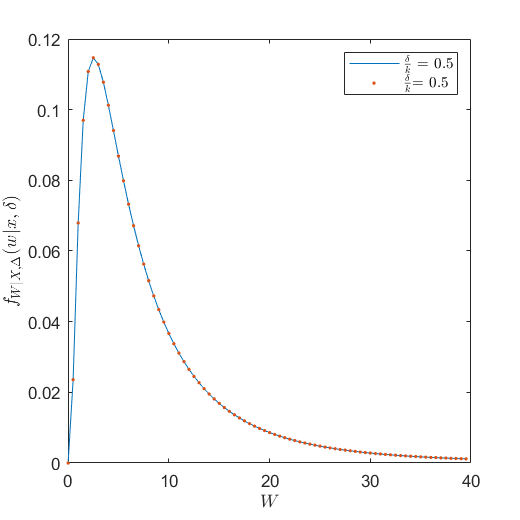

fig1=figure;
resize_figure(fig1,2*55,2*55);
mx = -0.25;
sx = 0.85;
xbin = 0.01:0.5:40;
d = 1;
k = 2;
plot(xbin,fwgxd(xbin,15,5,mz(mx,sx),sz(mx,sx),10));
hold on;
plot(xbin,fwgxd(xbin,15,d,mz(mx,sx),sz(mx,sx),k),'.');
set(gca,'XScale','linear');
xlabel('$W$','Interpreter','latex');
ylabel('$f_{W|X,\Delta}(w|x,\delta)$','Interpreter','latex');
legend('$\frac{\delta}{k}$ = 0.5',['$\frac{\delta}{k}$= ',num2str(d/k,2)],'Interpreter','latex');

## Likelihood function$F_{W|X}(w|x)
$

By integrating away $\delta
$, we get $F_{W|X}(w|x)
 = f(\sigma_{\delta}/k,x)
$ , is a function of the ratio $\sigma_\delta/k
$. This is a result of the integration in eq.6, which is challenging to do analytically. As a result it is surprising that it a function of the ratio $\sigma_\delta/k
$, which we call here the **effective temporal uncertainty**.  

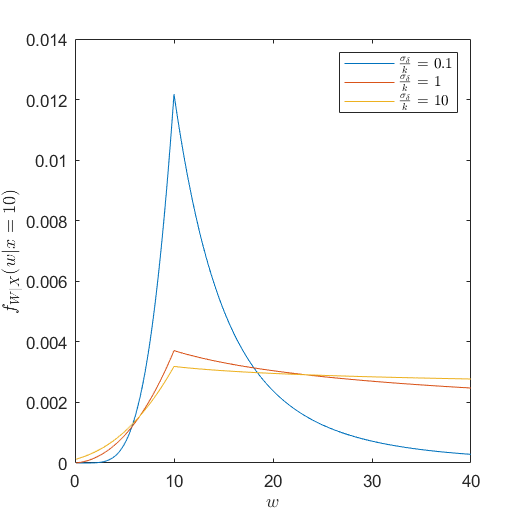

fig2=figure;
resize_figure(fig2,2*55,2*55);
mx = -0.25;
sx = 0.85;
xbin = 0.1:0.1:40;
ratio1 = 0.1;
ratio2 = 1; % k/sd
ratio3 = 10;
y1 = fwgx(10,xbin,mz(mx,sx),sz(mx,sx),1,ratio1);
y2 = fwgx(10,xbin,mz(mx,sx),sz(mx,sx),1,ratio2);
y3 = fwgx(10,xbin,mz(mx,sx),sz(mx,sx),1,ratio3);
plot(xbin,y1./trapz(y1)); % Note: we are plotting normalized pdfs 
hold on;
plot(xbin,y2./trapz(y2));
hold on;
plot(xbin,y3./trapz(y3));
xlabel('$w$','Interpreter',"latex");
ylabel('$f_{W|X}(w|x=10)$','Interpreter','latex')
legend(['$\frac{\sigma_{\delta}}{k}$ = ',num2str(ratio1)], ...
    ['$\frac{\sigma_{\delta}}{k}$ = ',num2str(ratio2)], ...
    ['$\frac{\sigma_{\delta}}{k}$ = ',num2str(ratio3)],'Interpreter','latex');
set(gca,'XScale','linear');

## Posterior probability distribution$F_{X|W}(x|w)
$

From eq.5, eq.6, and eq.7, we $F_{X|W}(x|w)
 = f(\sigma_{\delta}/k,w)
$ , which also remains a function of the ratio $\sigma_\delta/k
$. As the **effective temporal uncertainty** decreases, the probability that $X
$ (a.k.a true value) is close to what is measured $W$increases. 

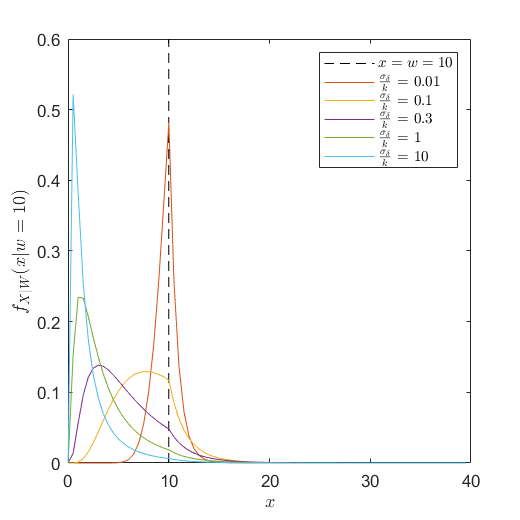

fig3=figure;
resize_figure(fig3,2*55,2*55);
mx = -0.25;
sx = 0.85;
xbin = 0.01:0.5:40;
ratio = 0.01; % sd/k
ratio1 = 0.1;
ratio2 = 0.3;
ratio3 = 1;
ratio4 = 10;
plot(10.*ones(1,10),linspace(0,0.6,10),'--k');
hold on;
plot(xbin,nFxgw(10,xbin,mx,sx,1,ratio));
hold on;
plot(xbin,nFxgw(10,xbin,mx,sx,1,ratio1));
hold on;
plot(xbin,nFxgw(10,xbin,mx,sx,1,ratio2));
hold on;
plot(xbin,nFxgw(10,xbin,mx,sx,1,ratio3));
hold on;
plot(xbin,nFxgw(10,xbin,mx,sx,1,ratio4));
xlabel('$x$','Interpreter',"latex");
ylabel('$f_{X|W}(x|w=10)$','Interpreter','latex')
legend( '$x=w=10$',...
    ['$\frac{\sigma_{\delta}}{k}$ = ',num2str(ratio)],...
    ['$\frac{\sigma_{\delta}}{k}$ = ',num2str(ratio1)], ...
    ['$\frac{\sigma_{\delta}}{k}$ = ',num2str(ratio2)], ...
    ['$\frac{\sigma_{\delta}}{k}$ = ',num2str(ratio3)], ...
    ['$\frac{\sigma_{\delta}}{k}$ = ',num2str(ratio4)], ...
    'Interpreter','latex');
set(gca,'XScale','linear');

wbin = 0.01:0.5:40;
xbin = 0.01:0.5:40;
Z = zeros(length(wbin),length(xbin));
for i = 1:length(wbin)
    Z(i,:)=nFxgw(wbin(i),xbin,mx,sx,1,ratio2);
end

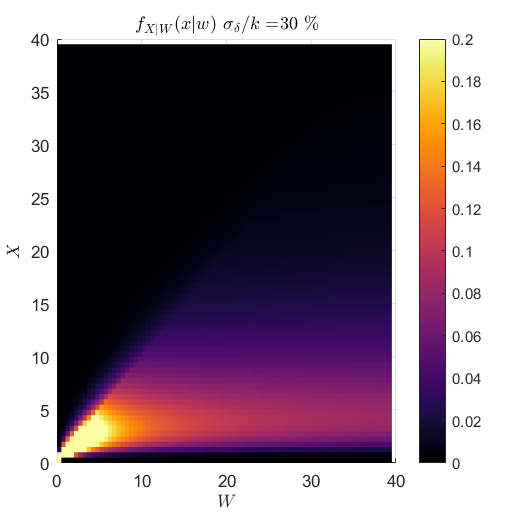

fig4=figure;
resize_figure(fig4,2*55,2*55);
colormap('inferno');
surf(wbin,xbin,Z','EdgeColor','none');
view(2);
xlabel('$W$','Interpreter','latex');
ylabel('$X$','Interpreter','latex');
colorbar();
set(gca,'ColorScale','linear');
caxis([0 0.2]);
title(['$f_{X|W}(x|w)$ $\sigma_\delta/k = $',num2str(100*ratio2),' \%'],'Interpreter','latex');
xlim([0,40]);
ylim([0,40]);

## Result: Non-linearity in $$\langle X|W \rangle$$increases with effective temporal uncertainty $\sigma_\delta /k$

The figure shows, non-linearity increasing with effective temporal uncertainty. This proves the claim that "uncertainty in measurement time can create a perception of non-linear bias in the systems response", if $X
$ drives some output $Y_{out}
$, and we regress $Y_{out}
$ with $X$. Furthermore, if $X$ propagates through a system, and$W=X(t+\Delta)
$ is read as output at the other end, then this system's response can apprear to be non-linear - especially if there is more than $$10\%$$ effective temporal uncertainty. For a 30% temporal uncertainty, the true regression function is at least 400% higher than when the function saturates at the highest value of the erroneous input $W=40$ units. 

wbin = 1:1:40;
xT = zeros(1,length(wbin));
xT1 = nExgw(wbin,mx,sx,100,1);
xT2 = nExgw(wbin,mx,sx,10,1);
xT3 = nExgw(wbin,mx,sx,3,1);
xT4 = nExgw(wbin,mx,sx,1,1);
xT5 = nExgw(wbin,mx,sx,0.1,1);

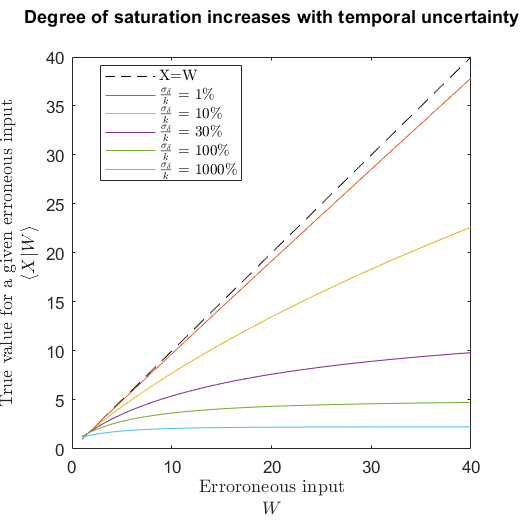

figM4=figure;
resize_figure(figM4,2*55,2*55);
plot(wbin,wbin,'--k');
hold on;
plot(wbin,xT1);
hold on;
plot(wbin,xT2);
hold on;
plot(wbin,xT3);
hold on;
plot(wbin,xT4);
hold on;
plot(wbin,xT5);
title('Degree of saturation increases with temporal uncertainty',' ','Interpreter','none')
xlabel({'Erroroneous input','$W$'},'Interpreter','Latex');
ylabel({'True value for a given erroneous input','$\langle X|W \rangle$'},'Interpreter','Latex');
legend(['X=W'],...
    ['$\frac{\sigma_{\delta}}{k}$ = $1\%$'], ...
    ['$\frac{\sigma_{\delta}}{k}$ = $10\%$'], ...
    ['$\frac{\sigma_{\delta}}{k}$ = $30\%$'], ...
    ['$\frac{\sigma_{\delta}}{k}$ = $100\%$'], ...
    ['$\frac{\sigma_{\delta}}{k}$ = $1000\%$'], ...
    'Interpreter','latex','Location','Best');
export_fig([outputFolder,'FigureM4.png'], ...
    '-r600','-png','-nocrop',figM4);
export_fig([outputFolder,'FigureM4.pdf'], ...
    '-r600','-pdf','-nocrop',figM4);